# Assignment 1

clear
rng(10)
addpath('functions')


## Question 1.1

s11.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s11.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

% % minreal tol = 0.1:
% s11.A = [1	-2.93295410542636	2.86674486023263	-0.933788061325452];
% s11.B = [0.445336800000000	-1.28889959687027	1.27642094733644	-0.432595129042807];


% % minreal tol = 0.5:
% s11.A = [1	-1.94279490608771	0.943068611541607];
% s11.B = [0.445336800000000	-0.846978049756568	0.435938305615007];

% Est
% s11.A = [1	-0.628054600018803	-0.340780053692741	-0.123253583434919	0.0964114956017608];
% s11.B = [0.154187616014832	-0.156669833035350	0.0706699303652418	0.0359340974766847	0.392677261233270];


## Question 1.2

syms yt_1 yt_2 yt_3 yt_4 u_0 u_1 u_2 u_3 u_4 
phi =  [yt_1 yt_2 yt_3 yt_4 u_0 u_1 u_2 u_3 u_4]';
theta = [3.88098254,5.64726905,-3.6515443,0.88525793,0.4453368,-1.7110786,2.49838163,-1.64272524,0.41012833]';
yt = vpa(phi'*theta)

$$yt = 0.44533679999999997711768173758173\,u_{0}-1.7110786000000000051102233555866\,u_{1}+2.4983816299999999088754520926159\,u_{2}-1.6427252400000000864821458890219\,u_{3}+0.41012832999999998540019419124292\,u_{4}+3.8809825400000002026956735790009\,{\mathrm{yt}}_{1}+5.6472690500000002344904714846052\,{\mathrm{yt}}_{2}-3.6515442999999998541227341775084\,{\mathrm{yt}}_{3}+0.88525792999999997068272250544396\,{\mathrm{yt}}_{4}$$

## Question 1.3

Stable with no stochastic term:

eigs = roots(s11.A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


## Question 1.4

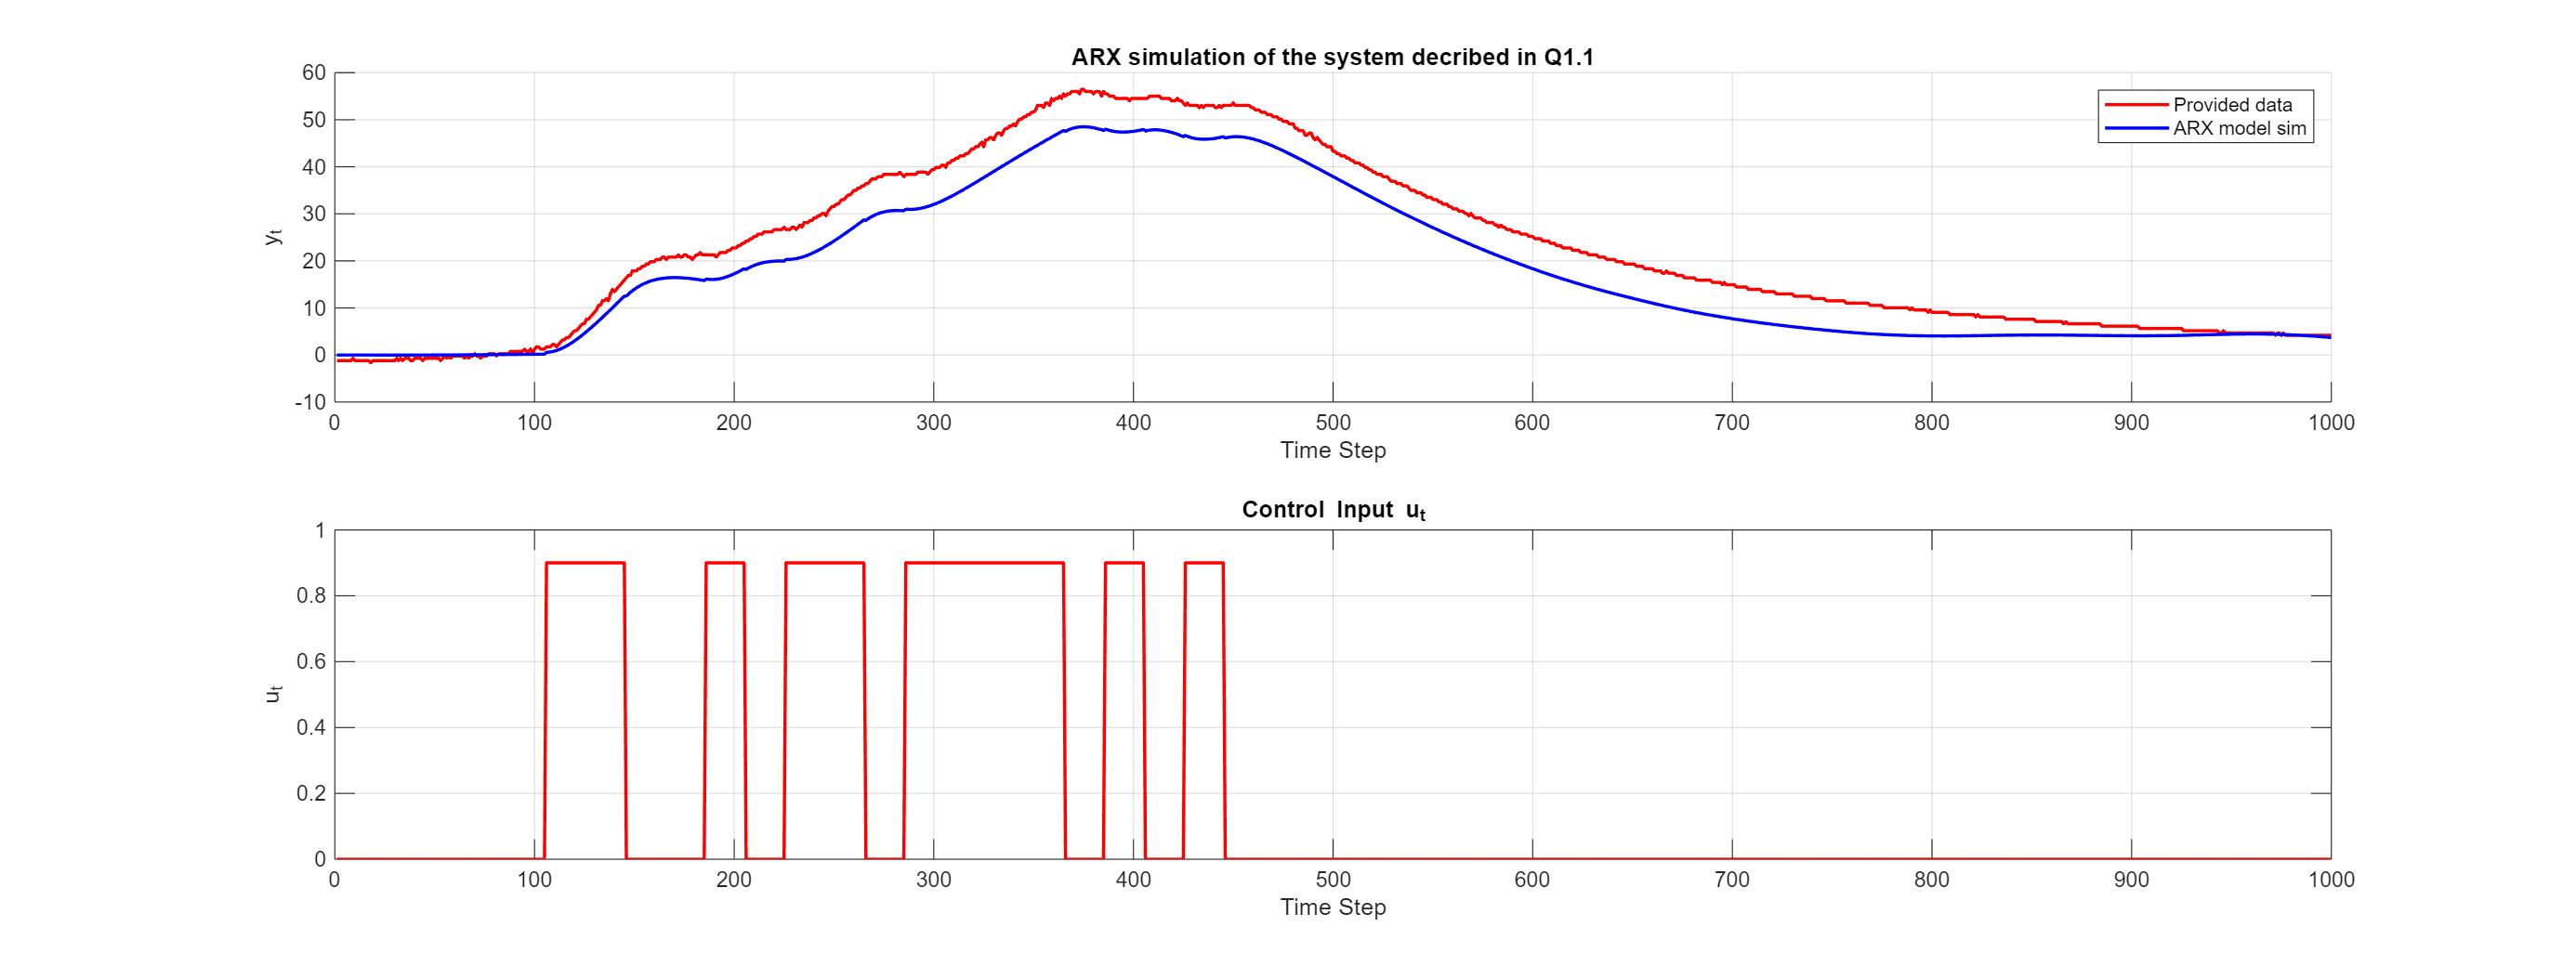

data = readmatrix('Assignment1_ObservationsAndInputs.txt')';
s14 = s11;

%% System Parameters
s14.N = 1000;  % Number of time steps
s14.y_data = data(1:s14.N,1);
s14.u_data = data(1:s14.N,2);
s14.sigma_e = sqrt(10^-10);  % Standard deviation of process noise
s14.mu = 0;
% s14.sigma_e = 0.00001;
s14.k = 0;  % Input delay
s14.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s14.A),length(s14.B)]);
s14.u_init = zeros(n_max,1);
s14.y_init = zeros(n_max,1);
s14.ref = data(1:s14.N,2);
s14.e = normrnd(s14.mu, s14.sigma_e,s14.N,1);

% % Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% % Stochastic(Stochastic) (True [1],  False [2])
% % Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
% SP = 1;
% Stochastic = 1;
% ctrl = 5;
% s14 = run_case(s14, SP, Stochastic, ctrl);


[s14.y,s14.u] = ARX(s14.A, s14.B, s14.e, s14.N, s14.k, s14.y_init, s14.u_init, s14.u_data);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s14.y_data, 'r', 'LineWidth', 1.5);
plot(s14.y(1:end), 'b', 'LineWidth', 1.5);
legend("Provided data", "ARX model sim")
hold off
title('ARX simulation of the system decribed in Q1.1');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s14.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.5

m = 100;
[G,S] = diophantine(s14.A,1,m)

G = 1.0e+04 *

    0.0001    0.0004    0.0009    0.0018    0.0031    0.0048    0.0070    0.0097    0.0130    0.0168    0.0212    0.0263    0.0319    0.0381    0.0450    0.0524    0.0605    0.0692    0.0785    0.0883    0.0987    0.1097    0.1212    0.1333    0.1458    0.1589    0.1724    0.1863    0.2007    0.2155    0.2307    0.2463    0.2622    0.2784    0.2950    0.3118    0.3290    0.3463    0.3639    0.3818    0.3998    0.4180    0.4363    0.4548    0.4735    0.4922    0.5111    0.5300    0.5490    0.5680


S = 1.0e+04 *

    1.4028   -4.0299    3.8585   -1.2314


R = conv(s14.B,G)

R = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


save('diophantine_sol.mat', 'G','S')
% -6.2470e+03	1.7705e+04	-1.7194e+04	5.7047e+03
% -6.1941e+03	1.7554e+04	-1.7046e+04	5.6551e+03 

## Question 1.6

s16 = s14;
m = 100

m = 100

y_pred = predict_m_steps(s16.A, s16.B, s16.y, s16.u_data, m, s16.N, s16.k);

% Compute Mean Absolute Error (MAE)
MAE = mean(abs(y_pred - s16.y));

% Display result
fprintf('Mean Absolute Error (MAE): %.5f\n', MAE);

Mean Absolute Error (MAE): 0.49773


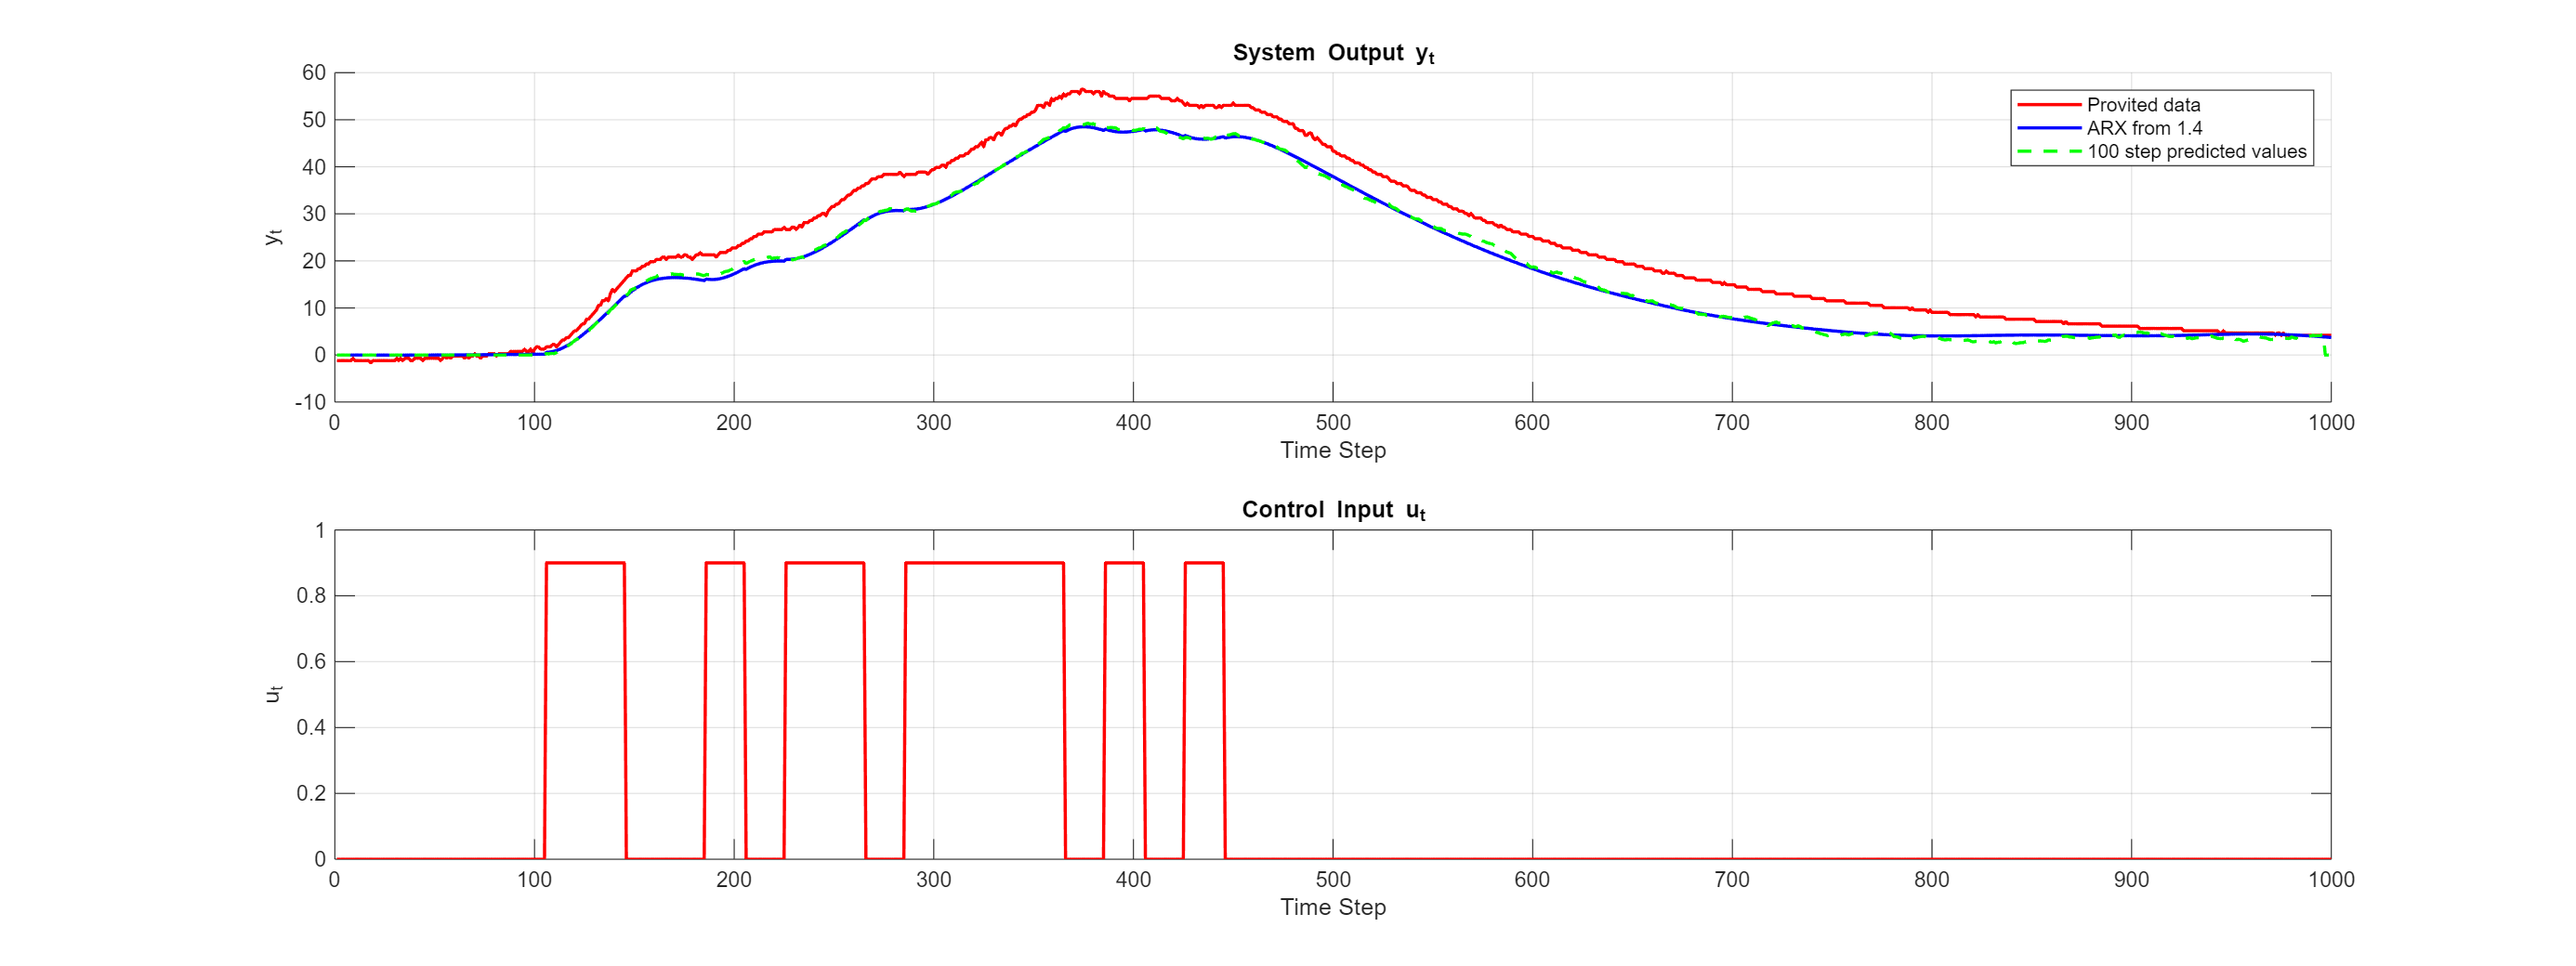


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s16.y_data, 'r', 'LineWidth', 1.5);
plot(s16.y(1:end), 'b', 'LineWidth', 1.5);

plot(y_pred, 'g--', 'LineWidth', 1.5);
legend("Provited data","ARX from 1.4", "100 step predicted values")
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s16.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.7

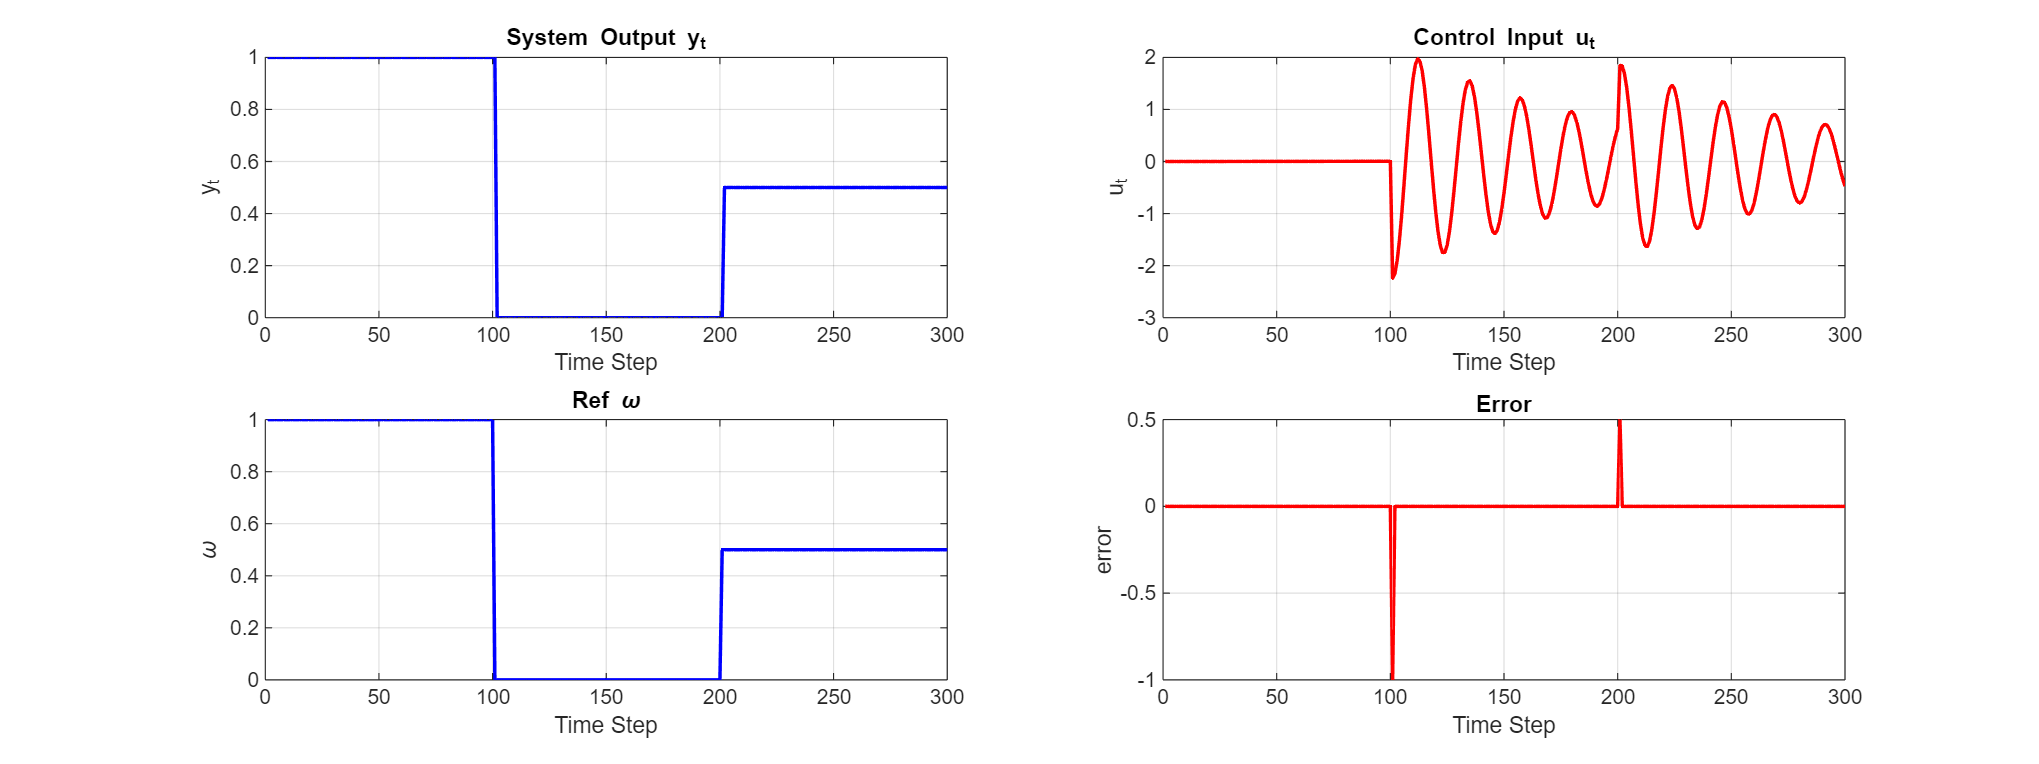

data = readmatrix('Assignment1_ObservationsAndInputs.txt')';
s17 = s16;
%% System Parameters
s17.N = 300;  % Number of time steps
s17.sigma_e = sqrt(10^-10);  % Standard deviation of process noise
s17.k = 1;  % Input delay
s17.alpha = 0.5; % Gain for P ctrl
n_max = max([length(s17.A),length(s17.B)]);
s17.u_init = zeros(n_max,1);
s17.y_init = ones(n_max,1);
s17.ref =  [ones(100,1);zeros(100,1);0.5*ones(100,1)];
s17.u_data = s17.ref;

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], u_data(:,2) [4], Off [5])
SP = 4;
Stochastic = 1;
ctrl = 3;
s17 = run_case(s17, SP, Stochastic, ctrl);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1);
plot(s17.y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,2,2);
plot(s17.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;
subplot(2,2,3)
plot(s17.omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
% ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,2,4)
plot(s17.omega-s17.y, 'r', 'LineWidth', 1.5);
title('Error');
xlabel('Time Step');
ylabel('error');
grid on;

## Question 1.8

% Construct the regression matrix Phi_t
% y_est_data = s.y;
s18 = s16;
y_est_data = s18.y_data;
u_est_data = s18.u_data;
% 
% [y_est_data,u_est_data] = ARX(s14.A_est, s14.B_est, s14.e, s14.N, s14.k, s14.y_init, s14.u_init,  idinput(s14.N, 'prbs', [0 1], [-1 1]);

% y_est_data = s14.y;
na = numel(s18.A) - 1;
nb = numel(s18.B) - 1;
% na = 2;
% nb = 2;

k = 0

k = 0

Phi = zeros(s18.N,na+ nb+1);
% for t = max(na,nb)+2+k:s18.N
%     Phi(t,:) = [-y_est_data(t-(1:na))', s18.u_data(t-k:-1:t-k-nb)']; %remember the sign sincee we are moviang y_t-n to right side
% end
% 
% % Solve for estimated parameters using least squares
% theta_hat = (Phi' * Phi) \ (Phi' * y_est_data);
% theta_hat = pinv(Phi)*y_est_data;

for t = max(na+1,nb+1)+k:s18.N
    Phi(t,:) = [-y_est_data(t-(1:na))', u_est_data(t-(k:nb))']; %remember the sign sincee we are moviang y_t-n to right side
end
% theta_hat = inv(Phi'*Phi)*Phi'*y_est_data;
theta_hat = pinv(Phi)*y_est_data;


% Display estimated vs true parameters
disp('Estimated Parameters:');

Estimated Parameters:


s18.A_est = [1,theta_hat(1:na)'];
s18.B_est = theta_hat(na+1:numel(Phi(1,:)))';
disp(['A_est: ', num2str(s18.A_est)])

A_est: 1    -0.71428    -0.39206   -0.086789     0.19582


disp(['B_est: ', num2str(s18.B_est)])

B_est: 0.3495      -0.179    -0.22865   -0.066223     0.43943



% Compute estimated parameter covariance matrix
sigma_sq_hat = var(y_est_data - Phi * theta_hat);  % Residual variance
cov_theta1 = sigma_sq_hat * inv(Phi' * Phi);  % Theoretical covariance


res = y_est_data - Phi * theta_hat;
res = res(5:end);
res_sum_sq = sum(res'*res);
res_var  = res_sum_sq/(numel(y_est_data)-numel(theta_hat)-5);
cov_theta2 = res_var * inv(Phi' * Phi);  % Theoretical covariance

disp('Estimated Variance of Parameters:');

Estimated Variance of Parameters:


disp(diag(cov_theta1)');  % Display variance of each parameter

    0.0010    0.0016    0.0016    0.0010    0.0093    0.0184    0.0184    0.0178    0.0093



disp(diag(cov_theta2)');  % Display variance of each parameter

    0.0010    0.0015    0.0015    0.0010    0.0088    0.0174    0.0174    0.0169    0.0088



% Compare with theoretical variance
theoretical_variance = s18.sigma_e^2 * inv(Phi' * Phi);
disp('Theoretical Variance of Parameters:');

Theoretical Variance of Parameters:


disp(diag(theoretical_variance)');

   1.0e-10 *

    0.0117    0.0184    0.0187    0.0116    0.1073    0.2132    0.2123    0.2064    0.1075



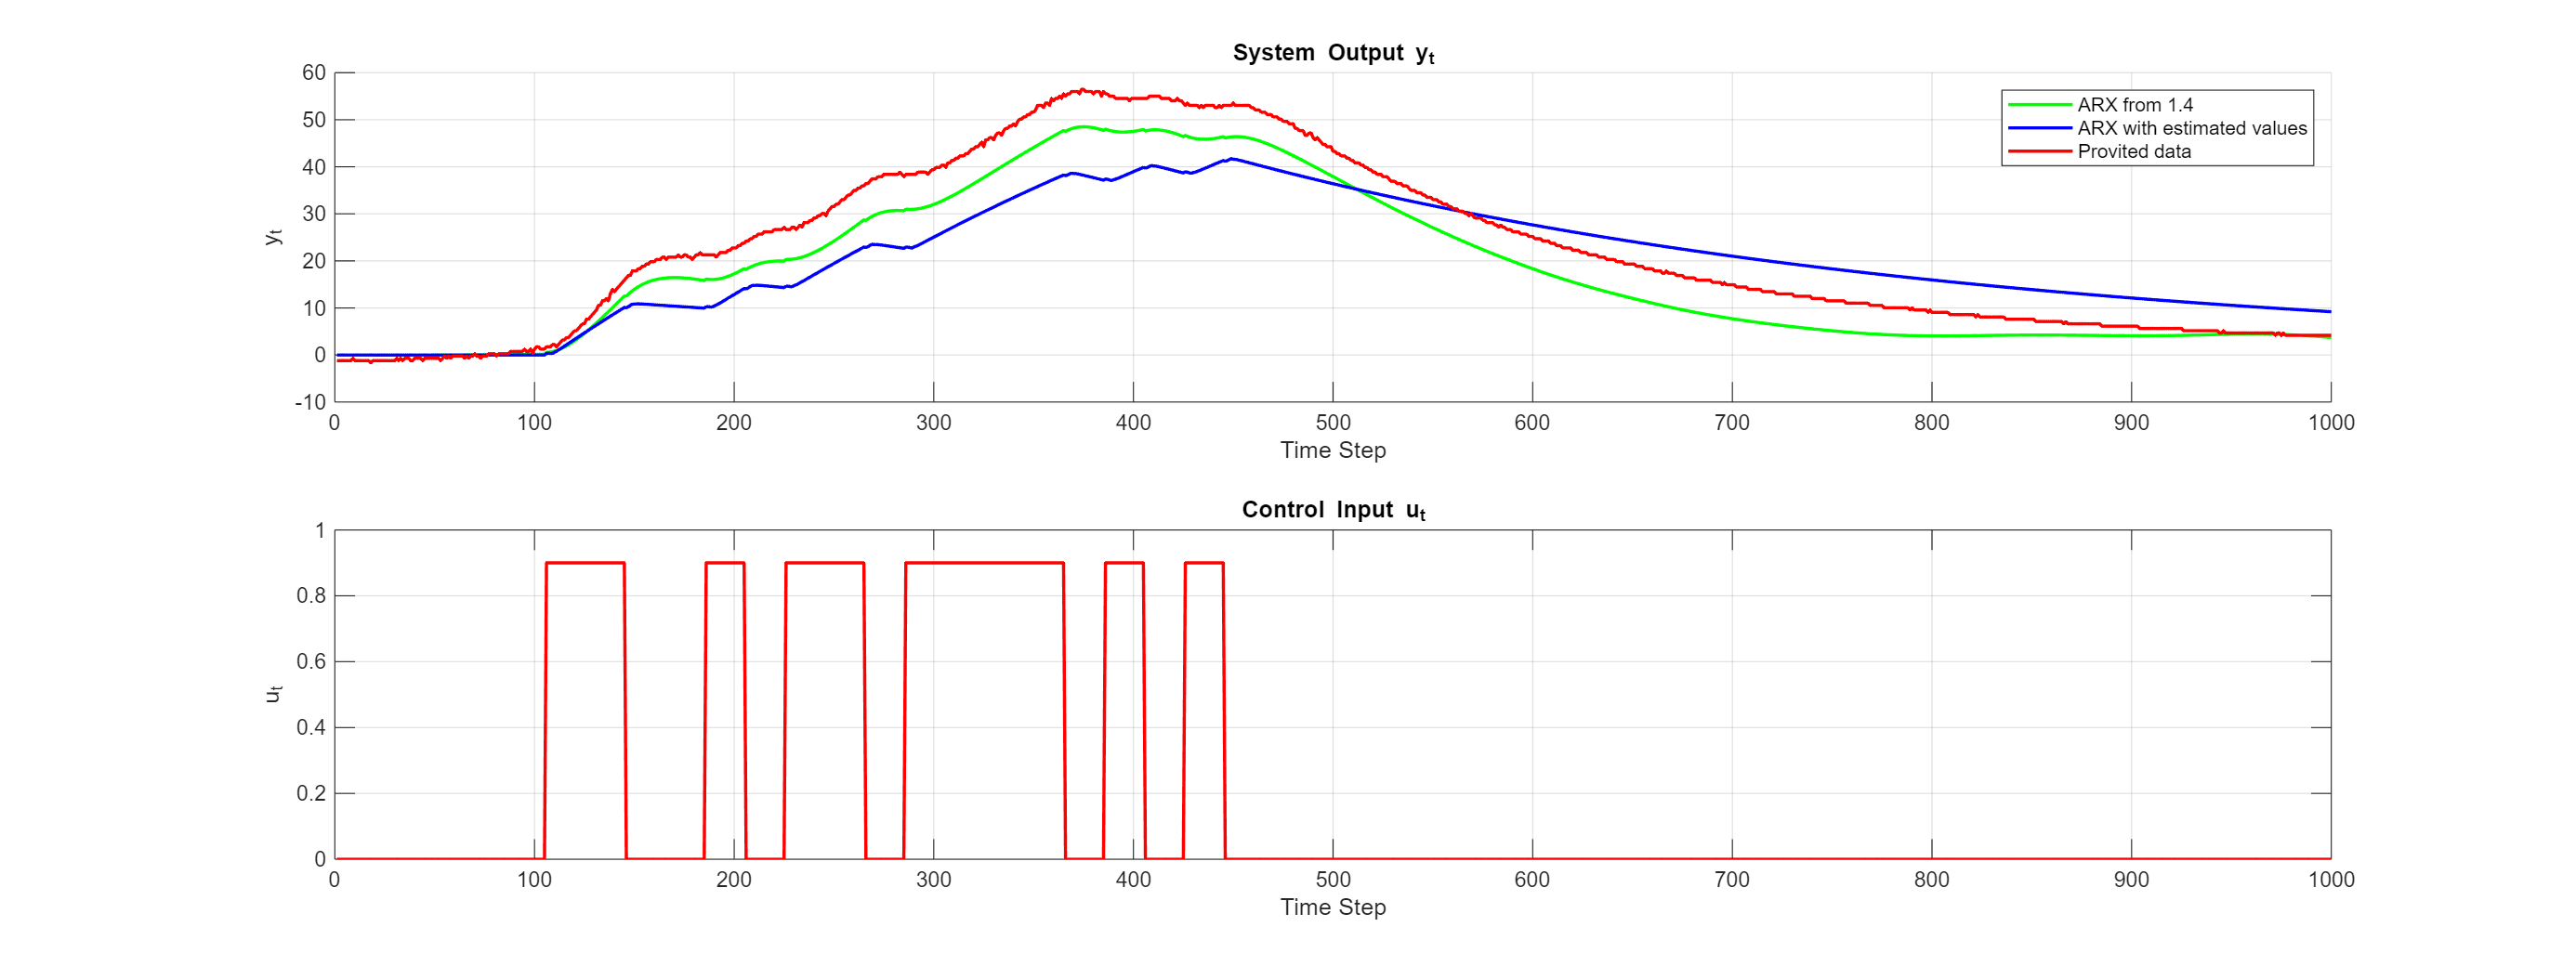


%% System Parameters
[s18.y,s18.u] = ARX(s18.A_est, s18.B_est, s18.e, s18.N, s18.k, s18.y_init, s18.u_init, s18.u_data);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s14.y(1:end), 'g', 'LineWidth', 1.5);
plot(s18.y(1:end), 'b', 'LineWidth', 1.5);
plot(s18.y_data, 'r', 'LineWidth', 1.5);
legend("ARX from 1.4", "ARX with estimated values", "Provited data")
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s18.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

### Predict with est values

m = 100

m = 100

y_pred = predict_m_steps(s18.A_est, s18.B_est, s18.y_data, s18.u_data, m, s18.N, s18.k);

% Compute Mean Absolute Error (MAE)
MAE = mean(abs(y_pred - s18.y_data));

% Display result
fprintf('Mean Absolute Error (MAE): %.5f\n', MAE);

Mean Absolute Error (MAE): 4.34435


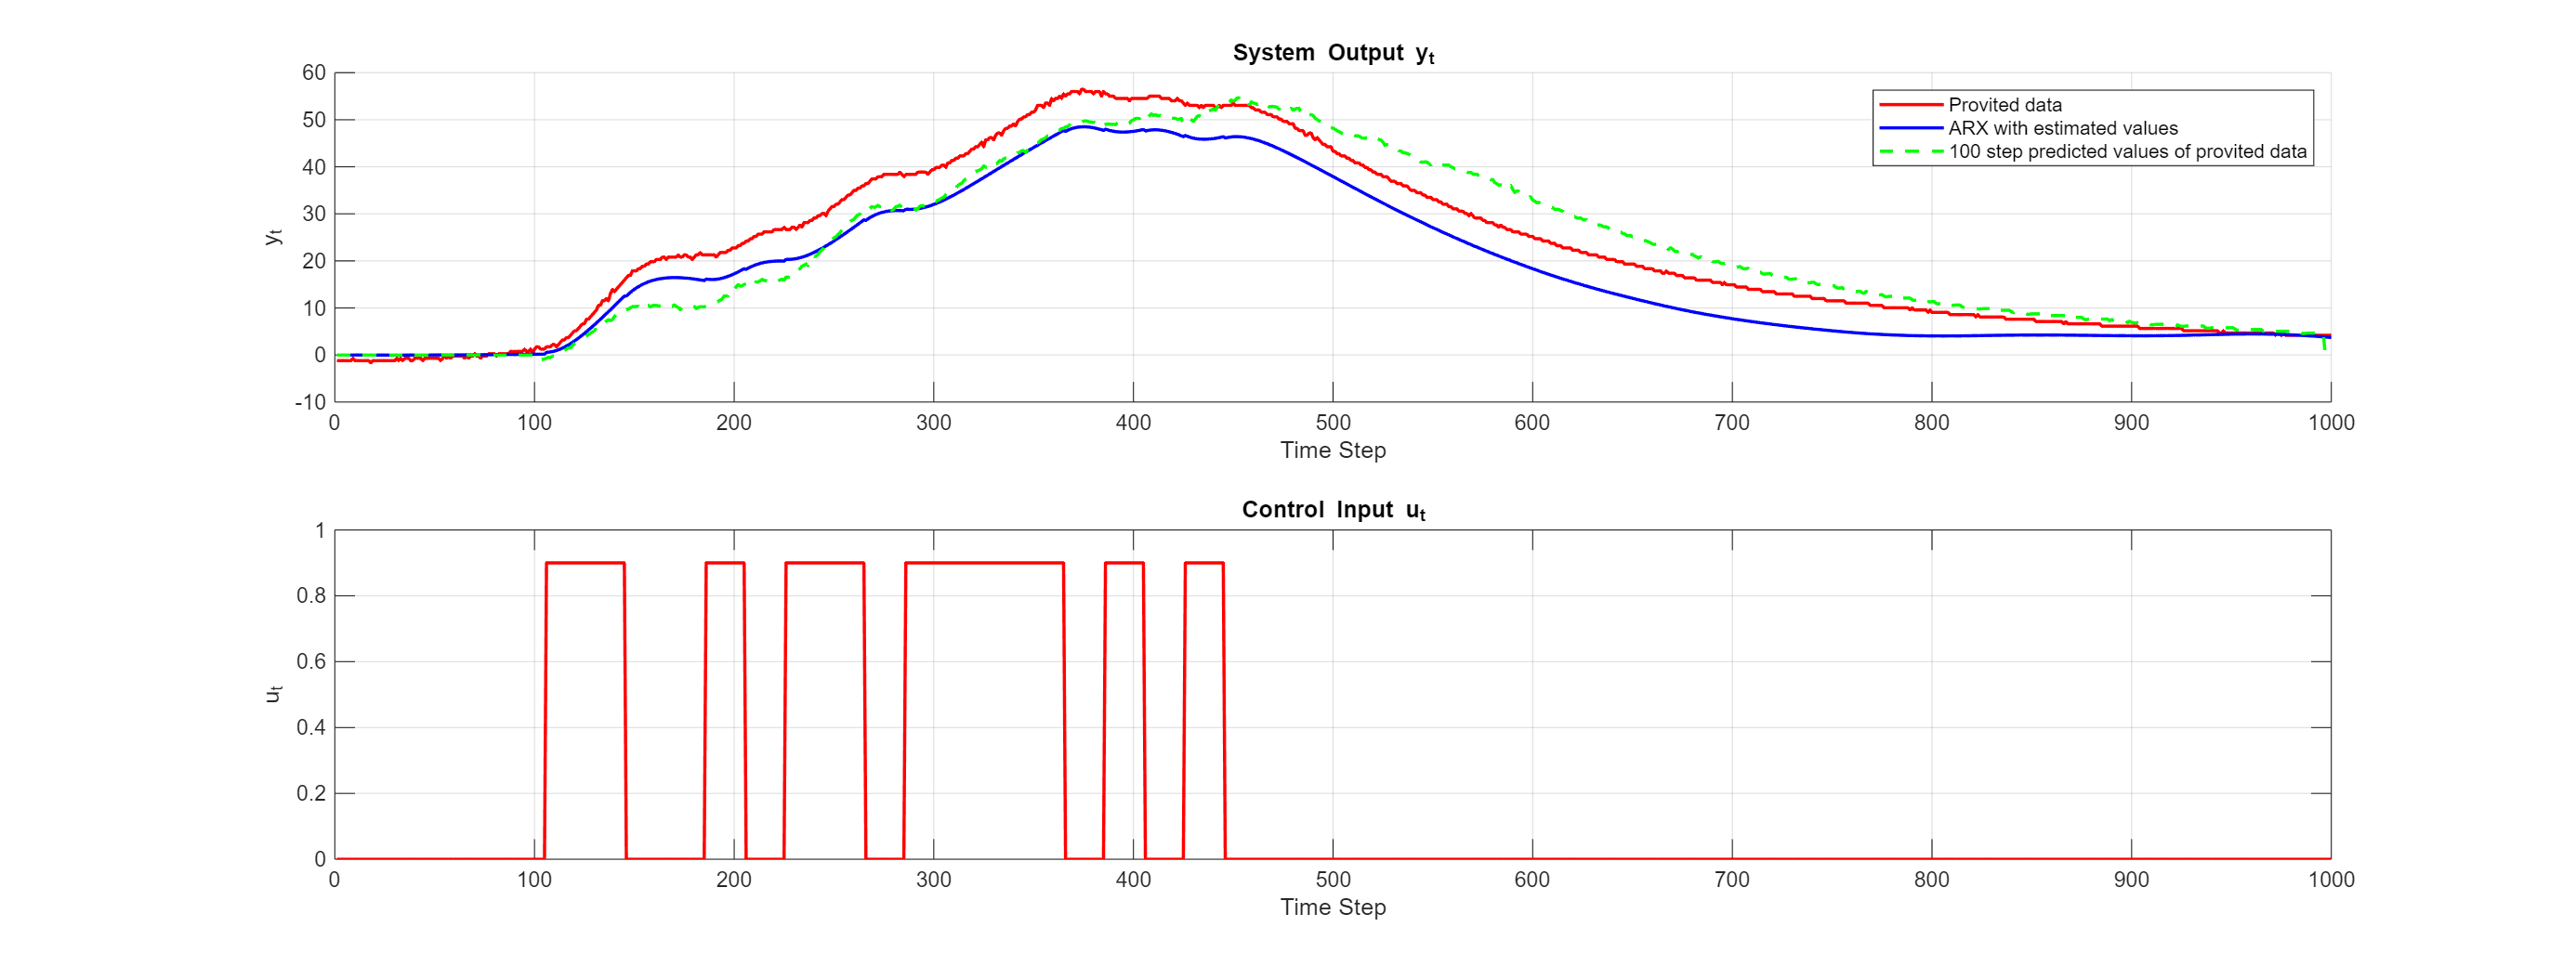


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s18.y_data, 'r', 'LineWidth', 1.5);
plot(s14.y, 'b', 'LineWidth', 1.5);
plot(y_pred, 'g--', 'LineWidth', 1.5);
legend("Provited data","ARX with estimated values", "100 step predicted values of provited data")
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s16.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

### PZ cancellation

sys_original = tf(s11.B, s11.A,1)


sys_original =
 
  0.4453 z^4 - 1.711 z^3 + 2.498 z^2 - 1.643 z + 0.4101
  -----------------------------------------------------
     z^4 - 3.881 z^3 + 5.647 z^2 - 3.652 z + 0.8853
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


zero(sys_original)

ans =    0.9509 + 0.2731i
   0.9509 - 0.2731i
   0.9923 + 0.0000i
   0.9481 + 0.0000i


sys_est = tf(s18.B_est, s18.A_est,1)


sys_est =
 
  0.3495 z^4 - 0.179 z^3 - 0.2287 z^2 - 0.06622 z + 0.4394
  --------------------------------------------------------
     z^4 - 0.7143 z^3 - 0.3921 z^2 - 0.08679 z + 0.1958
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


msys = minreal(sys_original,0.5)


msys =
 
  0.4453 z^2 - 0.847 z + 0.4359
  -----------------------------
     z^2 - 1.943 z + 0.9431
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


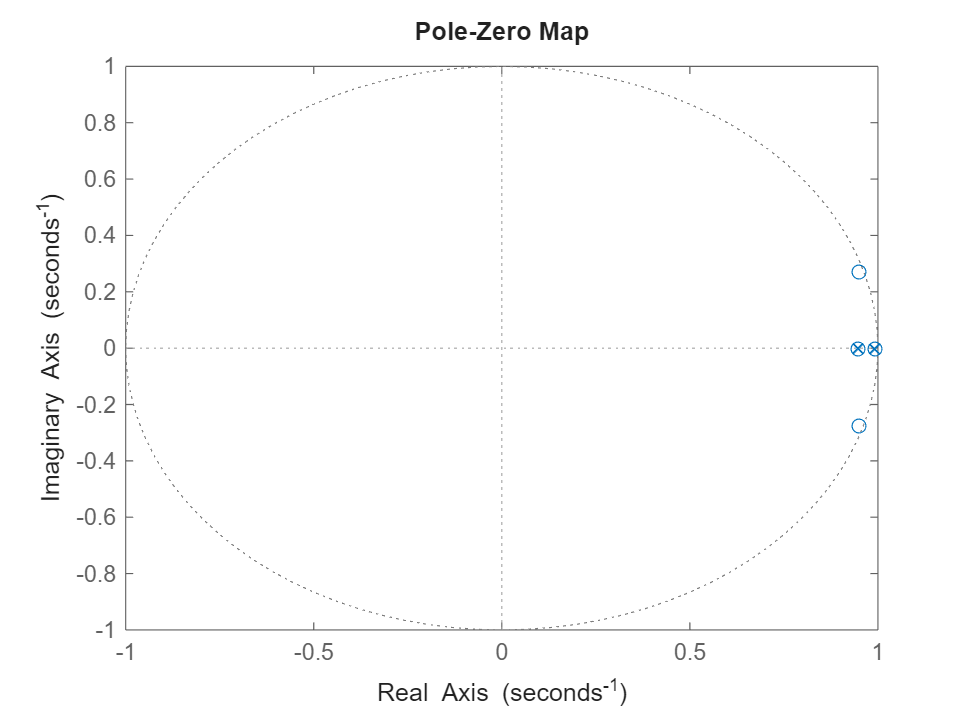

figure
pzplot(sys_original);

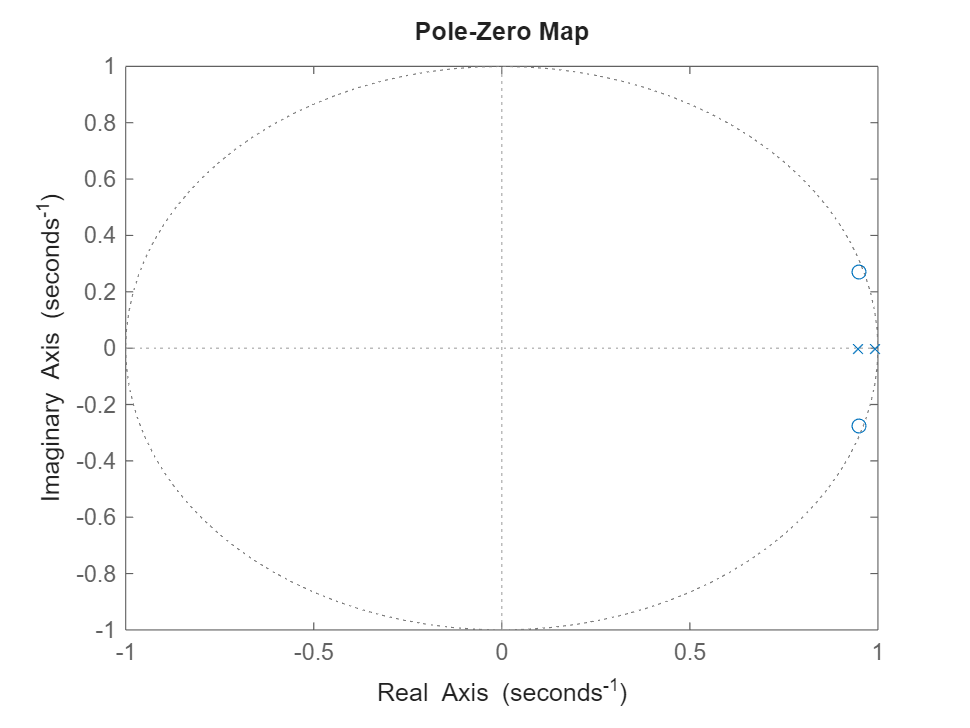

figure
pzplot(msys);

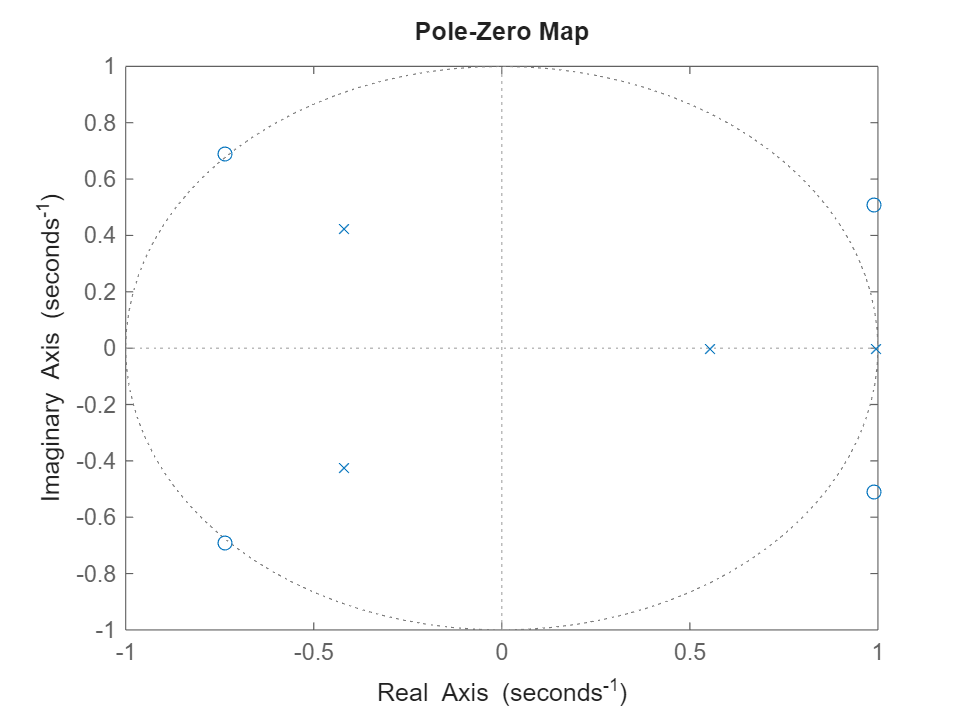

figure
pzplot(sys_est);

## Question 1.9

s19 = s16;
y_est_data = s19.y_data;
na = 4

na = 4

nb = 4

nb = 4

num = na + nb + 1

num = 9

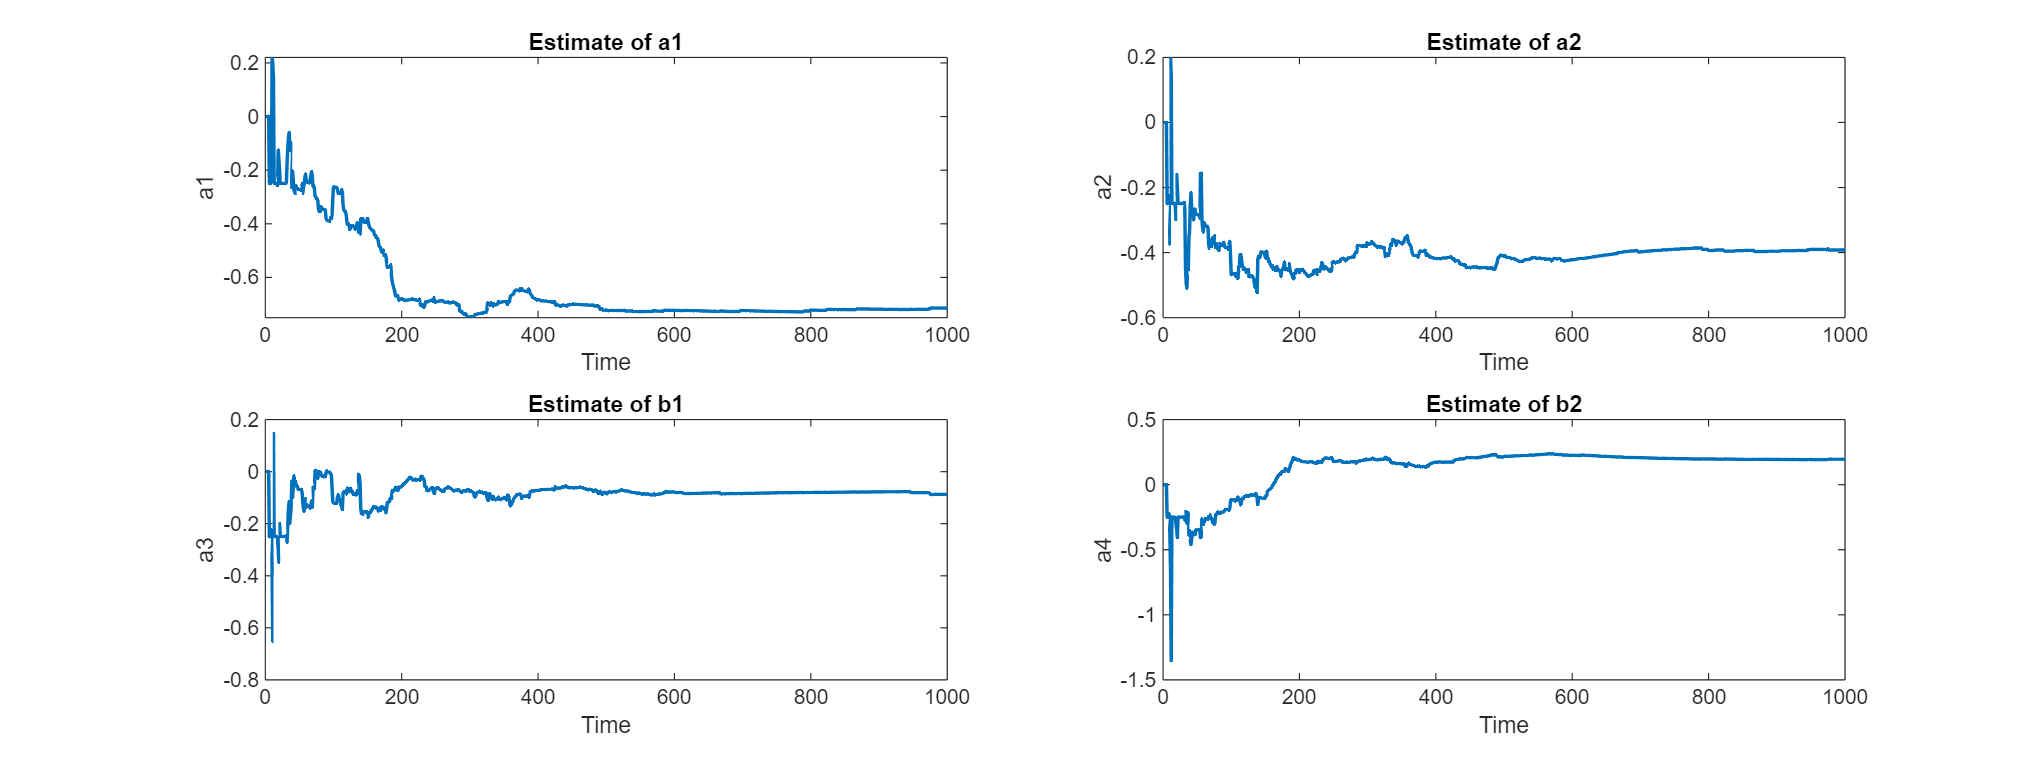

% Initialize Recursive Least Squares (RLS) Parameters
theta_rls = zeros(num, s19.N); % Store estimated parameters over time
P = 100*eye(num); % Initial covariance (high uncertainty)
lambda = 1; % Forgetting factor

theta_hat = zeros(num, 1); % Initial parameter estimates
P_plot = theta_hat;
% Recursive Estimation
for t = max([na+1,nb+1])+1:s19.N
    % Regression vector Phi_t
    Phi_t = [-y_est_data(t-(1:na))', s19.u_data(t-s19.k:-1:t-s19.k-nb)']';

    % Kalman gain
    K_t = P * Phi_t / (lambda + Phi_t' * P * Phi_t);
    
    % Prediction error
    e_t = y_est_data(t) - Phi_t' * theta_hat;
    
    % Parameter update
    theta_hat = theta_hat + K_t * e_t;
    
    % Covariance update
    P = (P - K_t * Phi_t' * P) / lambda;
    P_plot(:, t) = diag(P);
    
    
    % Store estimates over time
    theta_rls(:, t) = theta_hat;
end

% Plot parameter evolution
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1); plot(theta_rls(1,:), 'LineWidth', 1.5); title('Estimate of a1'); xlabel('Time'); ylabel('a1');
subplot(2,2,2); plot(theta_rls(2,:), 'LineWidth', 1.5); title('Estimate of a2'); xlabel('Time'); ylabel('a2');
subplot(2,2,3); plot(theta_rls(3,:), 'LineWidth', 1.5); title('Estimate of b1'); xlabel('Time'); ylabel('a3');
subplot(2,2,4); plot(theta_rls(4,:), 'LineWidth', 1.5); title('Estimate of b2'); xlabel('Time'); ylabel('a4');

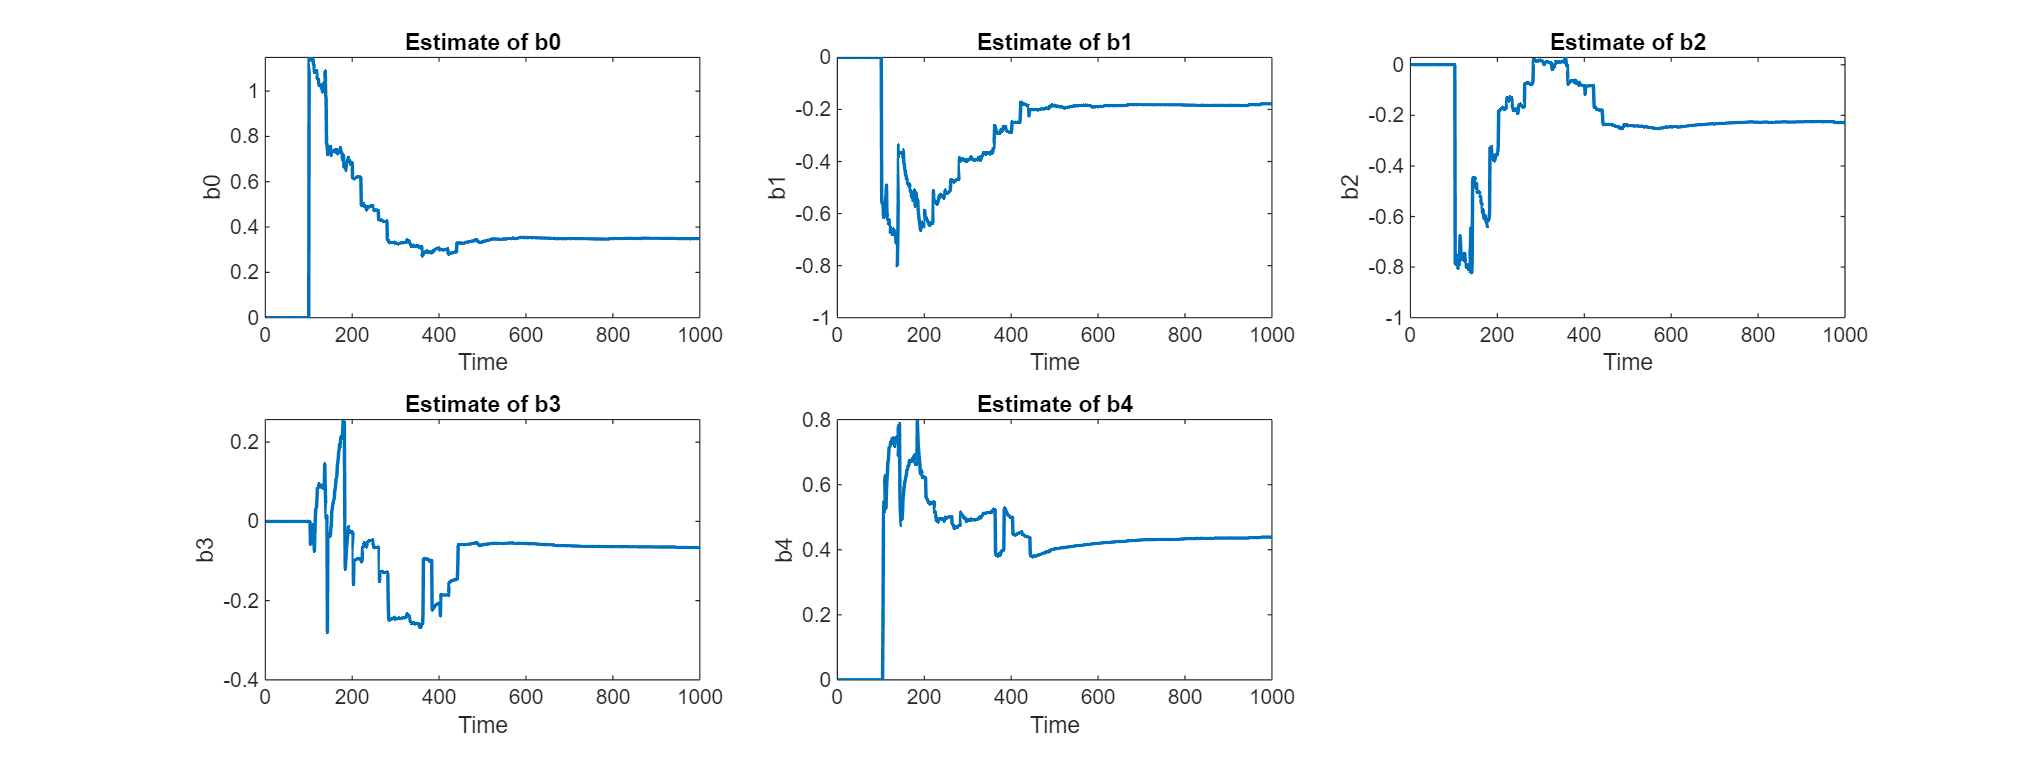

fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,3,1); plot(theta_rls(5,:), 'LineWidth', 1.5); title('Estimate of b0'); xlabel('Time'); ylabel('b0');
subplot(2,3,2); plot(theta_rls(6,:), 'LineWidth', 1.5); title('Estimate of b1'); xlabel('Time'); ylabel('b1');
subplot(2,3,3); plot(theta_rls(7,:), 'LineWidth', 1.5); title('Estimate of b2'); xlabel('Time'); ylabel('b2');
subplot(2,3,4); plot(theta_rls(8,:), 'LineWidth', 1.5); title('Estimate of b3'); xlabel('Time'); ylabel('b3');
subplot(2,3,5); plot(theta_rls(9,:), 'LineWidth', 1.5); title('Estimate of b4'); xlabel('Time'); ylabel('b4');

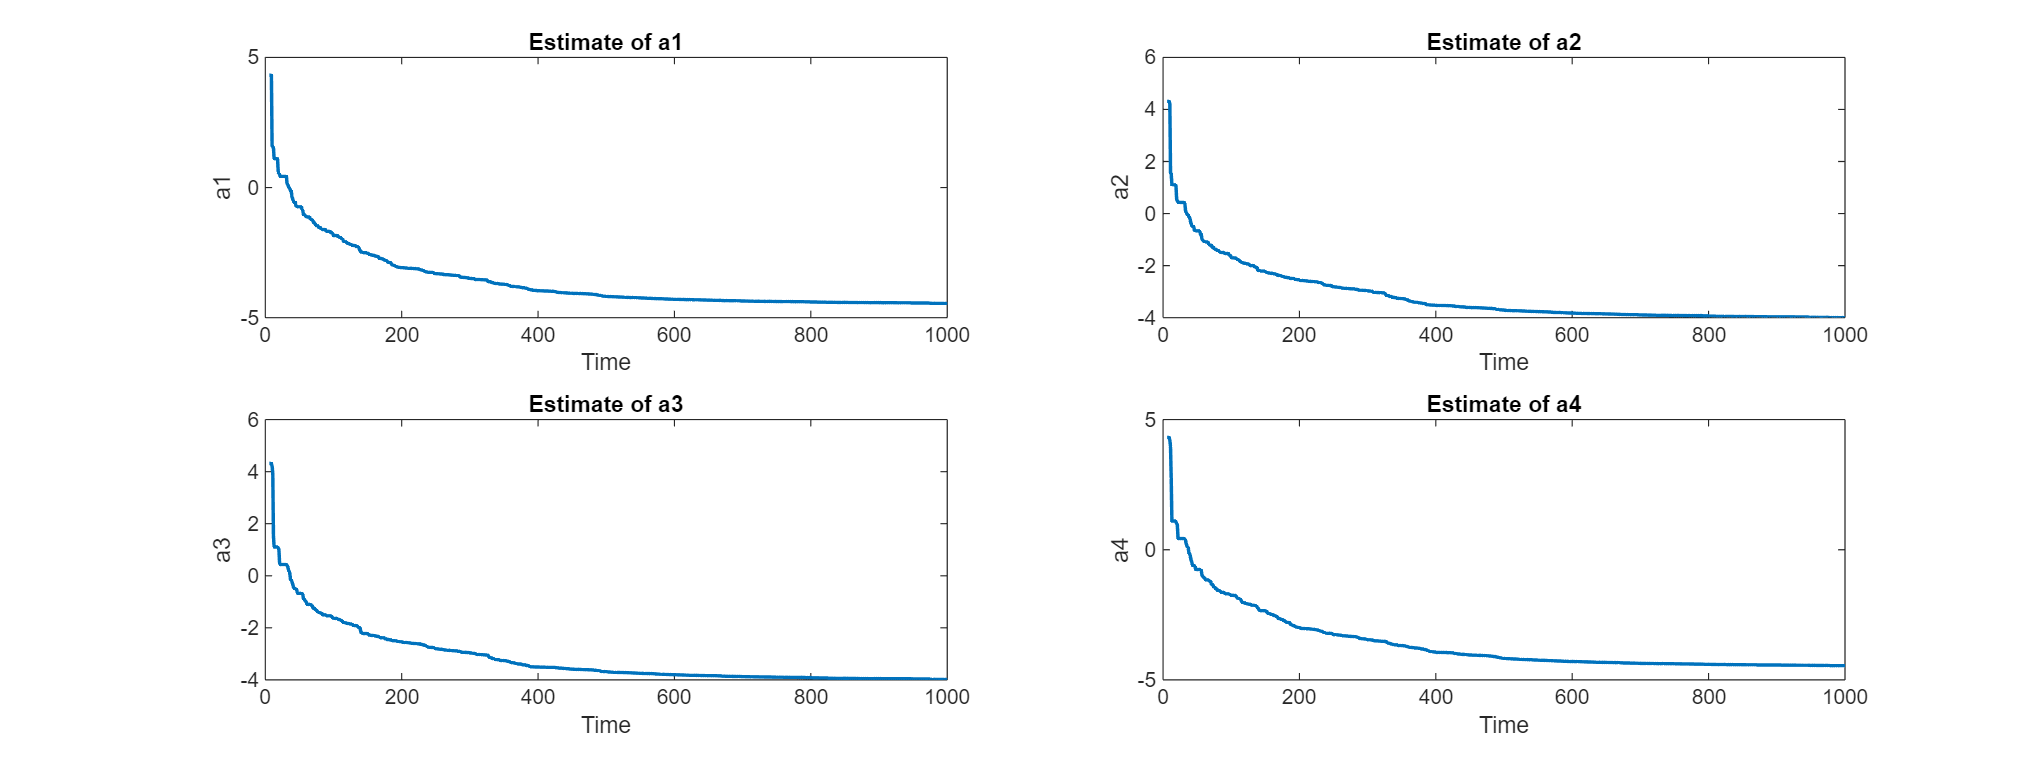

P_plot = log(P_plot);
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1); plot(P_plot(1,:), 'LineWidth', 1.5); title('Estimate of a1'); xlabel('Time'); ylabel('a1');
subplot(2,2,2); plot(P_plot(2,:), 'LineWidth', 1.5); title('Estimate of a2'); xlabel('Time'); ylabel('a2');
subplot(2,2,3); plot(P_plot(3,:), 'LineWidth', 1.5); title('Estimate of a3'); xlabel('Time'); ylabel('a3');
subplot(2,2,4); plot(P_plot(4,:), 'LineWidth', 1.5); title('Estimate of a4'); xlabel('Time'); ylabel('a4');

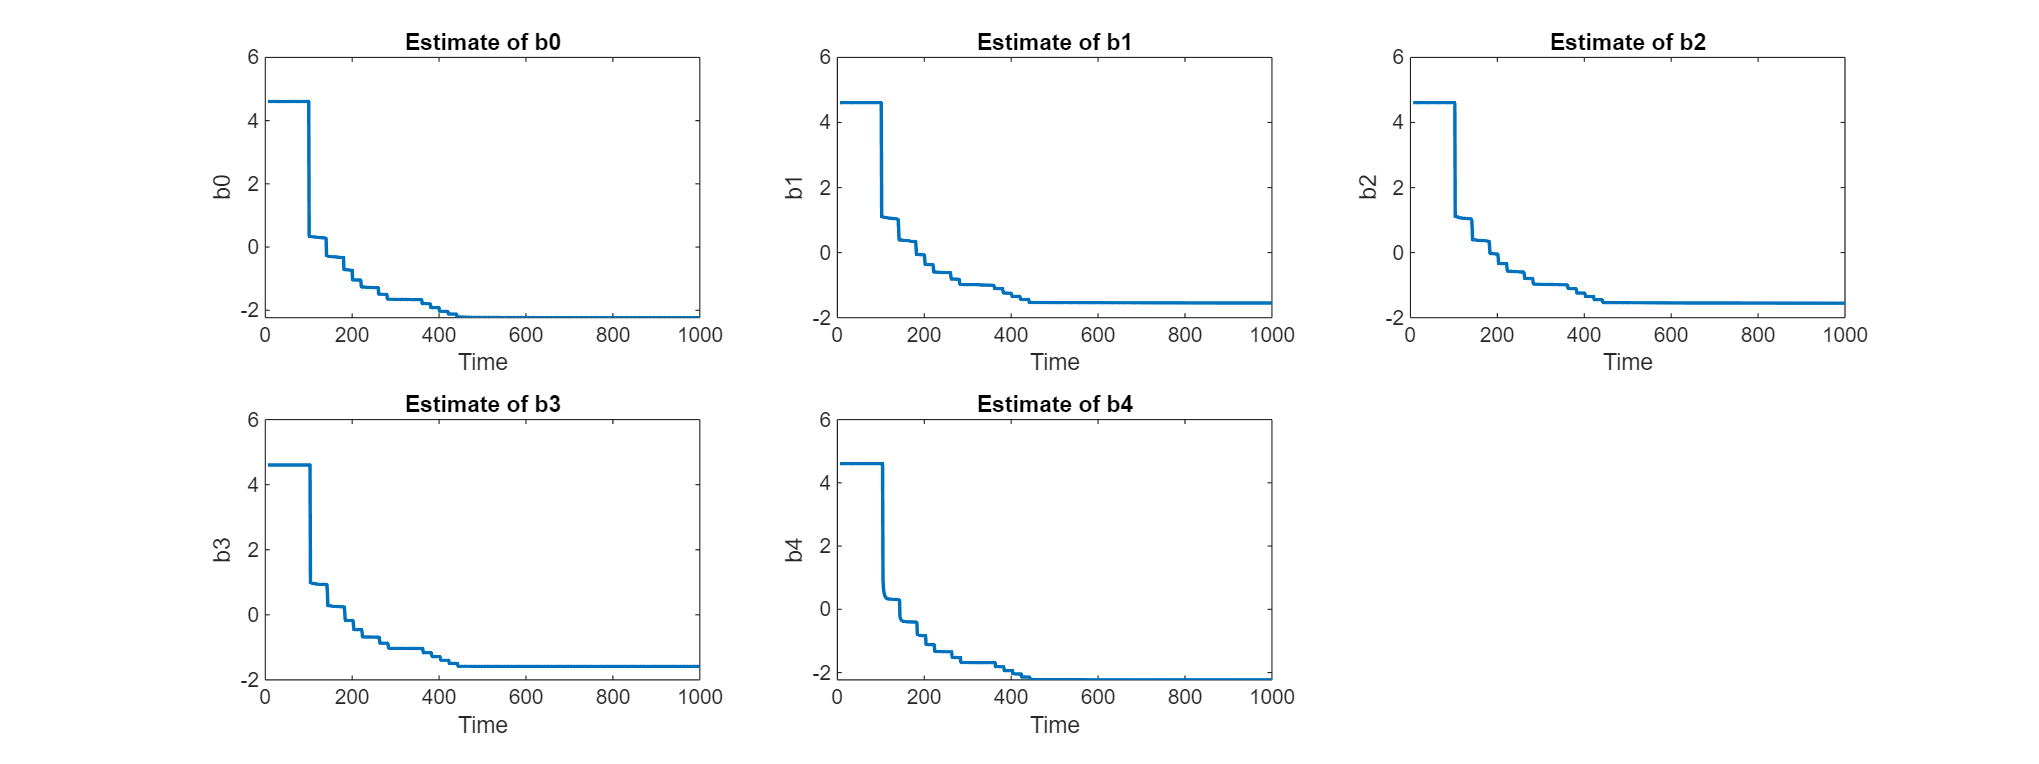

fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,3,1); plot(P_plot(5,:), 'LineWidth', 1.5); title('Estimate of b0'); xlabel('Time'); ylabel('b0');
subplot(2,3,2); plot(P_plot(6,:), 'LineWidth', 1.5); title('Estimate of b1'); xlabel('Time'); ylabel('b1');
subplot(2,3,3); plot(P_plot(7,:), 'LineWidth', 1.5); title('Estimate of b2'); xlabel('Time'); ylabel('b2');
subplot(2,3,4); plot(P_plot(8,:), 'LineWidth', 1.5); title('Estimate of b3'); xlabel('Time'); ylabel('b3');
subplot(2,3,5); plot(P_plot(9,:), 'LineWidth', 1.5); title('Estimate of b4'); xlabel('Time'); ylabel('b4');


















% Display final estimated parameters
disp('Final Estimated Parameters (Recursive LS):');

Final Estimated Parameters (Recursive LS):


disp(theta_hat');

   -0.7143   -0.3920   -0.0868    0.1958    0.3489   -0.1785   -0.2284   -0.0659    0.4389



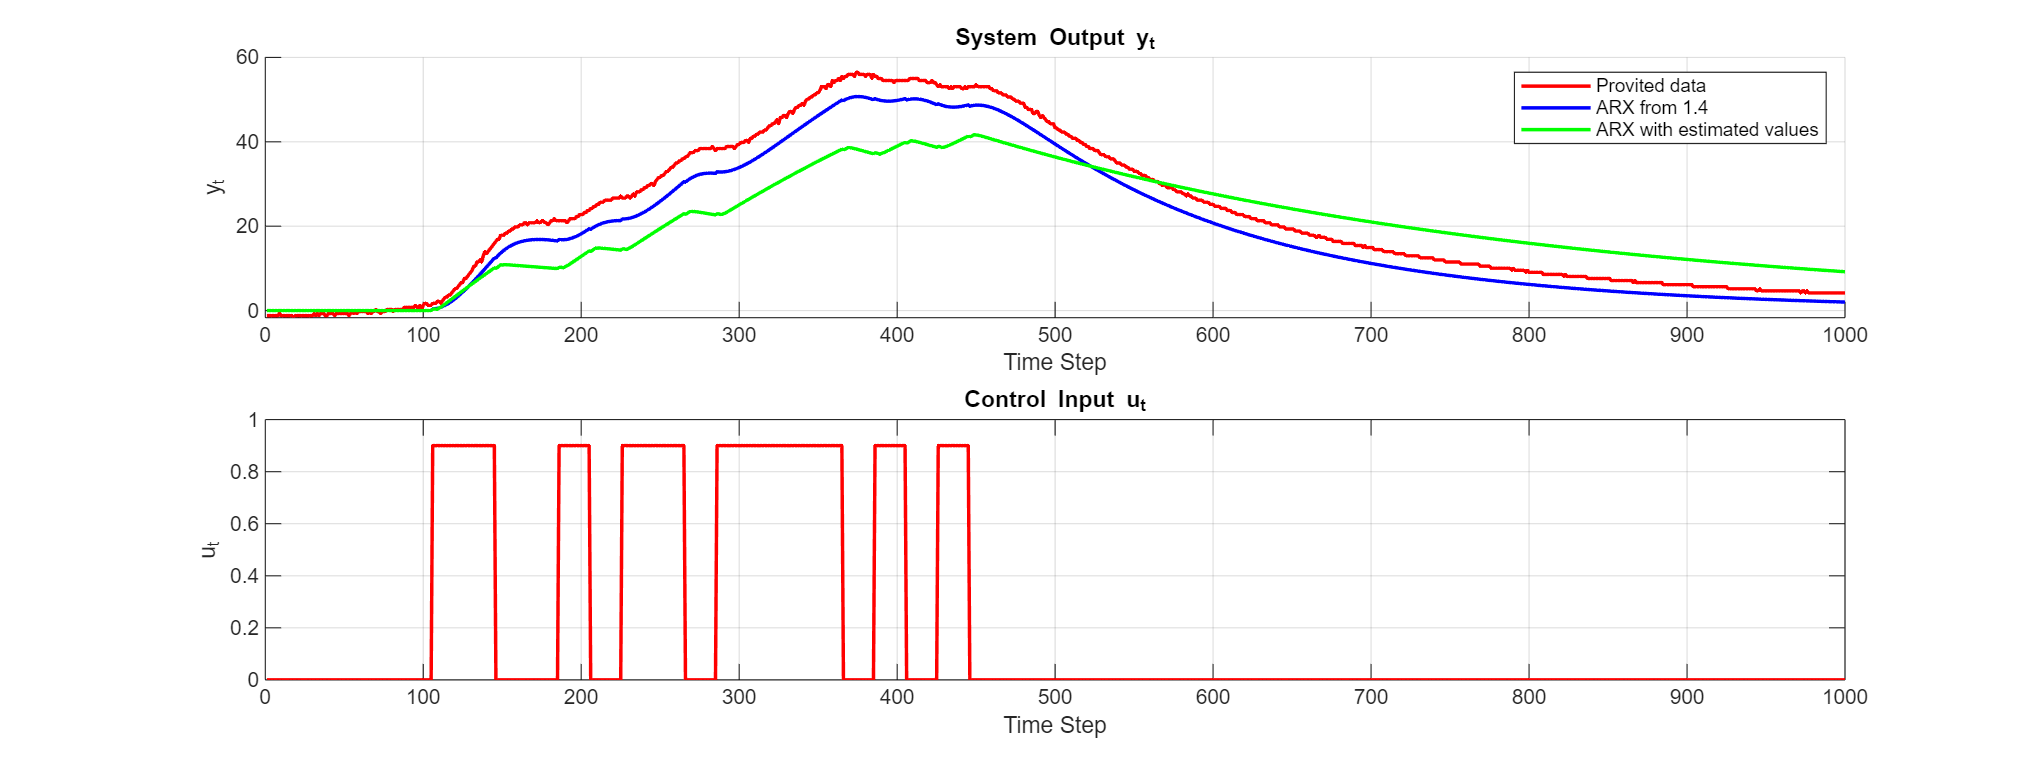


s19.A_est = [1,theta_hat(1:na)'];
s19.B_est = theta_hat(na+1:num)';
% % Compute estimated parameter covariance matrix
% sigma_sq_hat = var(y_est_data - Phi * theta_hat);  % Residual variance
% cov_theta = sigma_sq_hat * inv(Phi' * Phi);  % Theoretical covarianc

% disp('Estimated Variance of Parameters:');
% disp(diag(cov_theta)');  % Display variance of each parameter

% % Compare with theoretical variance
% theoretical_variance = s19.sigma_e^2 * inv(Phi' * Phi);
% disp('Theoretical Variance of Parameters:');
% disp(diag(theoretical_variance)');

[s19.y,s19.u] = ARX(s19.A_est, s19.B_est, s19.e, s19.N, s19.k, s19.y_init, s19.u_init, s19.u_data);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s19.y_data, 'r', 'LineWidth', 1.5);
plot(s14.y(1:end), 'b', 'LineWidth', 1.5);
plot(s19.y(1:end), 'g', 'LineWidth', 1.5);

legend("Provited data", "ARX from 1.4", "ARX with estimated values")
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s19.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

(s18.A_est - s19.A_est)./abs(s18.A_est)*100

ans =          0   -0.0017   -0.0128    0.0213    0.0225


(s18.B_est - s19.B_est)./abs(s18.B_est)*100

ans =     0.1646   -0.2858   -0.1061   -0.5078    0.1177


(s18.A_est - s19.A_est)

ans = 1.0e-04 *

         0   -0.1220   -0.5035    0.1849    0.4408


(s18.B_est - s19.B_est)

ans = 1.0e-03 *

    0.5754   -0.5115   -0.2426   -0.3363    0.5172
